# Tabletop problem for study 

This livescript builds a tabletop planning problem that consists of 

- a width x height world grid.

- an agent, can be a robot, satellite, uav, etc. The agent can move (up, down, left, right) or perform other actions, which deplete the battery

- a discretized battery model (4 states, [1,2,3,4], 1 is fully charged to steady state, 2 is steady state, 3 is steady to decline, 4 is decline - end of charge. [wip] --> moving one "normal" square depletes 3% soc, moving one "bad" square depletes 5% soc, taking a picture depletes 1%, transmitting the picture depletes 2% (some of this isn't implemented yet)

## General Setup

- The map

width = 4;
height = 3;

% start location
start = [1,1];
finish = start;

% location prototype
location.type = "normal"; 
location.label = "";

% map is a matrix of structs
map = repmat(location, width, height);

- The agent

agent.type = "robot";
agent.location = start;
agent.distance = 0;
agent.direction = '^';
agent.soc = 100;
agent.locationType = location.type;
agent.cumulativeReward = int16(0);

- actions (move up, down, left, right, observe, transmit

actions = ['^', 'v', '<', '>', 'o', 't'];

## Keep track of State

state.location = agent.location;
state.battery = 1;
state.achieved1 = false;
%state.achieved2 = false;

## The world grid

- add "points of interest"

- References are hard-coded throughout, however their location values, lengths, and names can be changed

- Update the locations here

poi.start = agent.location;
poi.objectives = [4,3];% [8,5; 2,6];
poi.pitfalls = [4,2];%[2,5; 4,1; 6,2; 8,2; 6,6; 6,7; 7,7];
poi.blocks = [2,2];%[1,4; 4,3; 6,3; 5,3; 2,2; 5,4; 5,5];

- update location names here

map(poi.start(1), poi.start(2)).type = "start";
for i=1:1%(length(poi.objectives))
    map(poi.objectives(i,1), poi.objectives(i,2)).type = "objective";
    map(poi.objectives(i,1), poi.objectives(i,2)).label = sprintf("O-%d", i);
end

for i=1:1%(length(poi.pitfalls))
    map(poi.pitfalls(i,1), poi.pitfalls(i,2)).type = "pitfall";
    map(poi.pitfalls(i,1), poi.pitfalls(i,2)).label = sprintf("P-%d", i);
end
for i=1:1%(length(poi.blocks))
    map(poi.blocks(i,1), poi.blocks(i,2)).type = "block";
end

### Visualize the grid world

- show location of robot and objects 

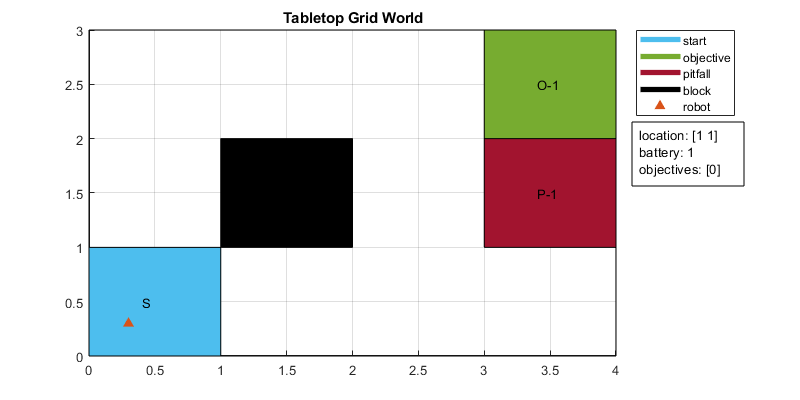

f1 = visualizeGridWorld(1, map, poi, state, agent);
title("Tabletop Grid World");

### [optional] Move the robot, and revisualize

- The robot cannot travel off of the grid or on a black spot

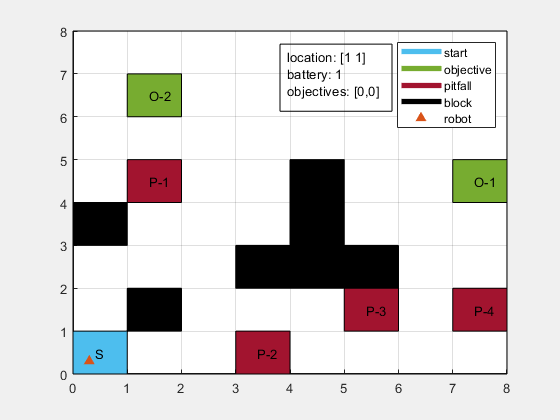

agent = moveAgent(agent, '>', 1, map, poi);
state = update_state(state, agent, map);
f2 = visualizeGridWorld(2, map, poi, state, agent);

### [optional] Robot Teleop

- reads arrow keys, q to quit (press enter to close pop up figure)

- run above block to generate figure 2

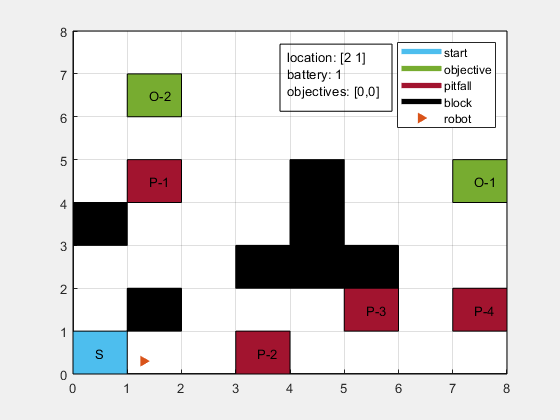

teleop(agent, 2, map, poi, state);

## Shortest path test

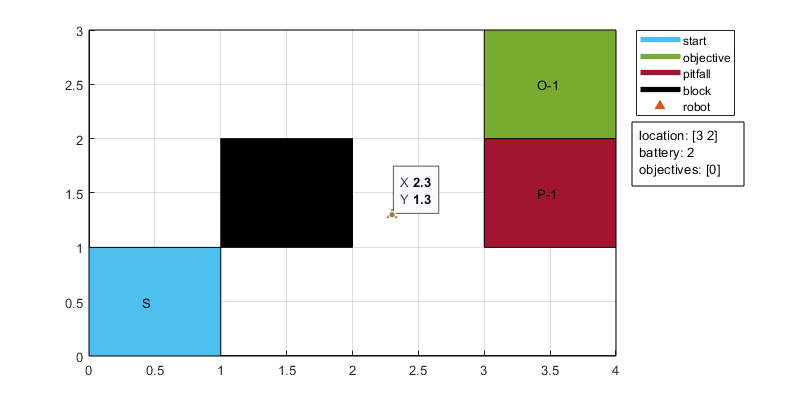

G = convert2graph(map, "block", "pitfall");
start_ID = 1;
obj1_ID = 8;%40;
%obj2_ID = 58;

[P, d, edgepath] = shortestpath(G, start_ID, obj1_ID);
dirs = get_path_directions(map, P);

%reset agent and state 
state.location = agent.location;
state.battery = 1;
state.achieved1 = false;
state.achieved2 = false;

agent = set_agent(agent, map, [1,1], 0, '^', 100, 1, 0);
for i=1:length(dirs)
    f3 = visualizeGridWorld(3, map, poi, state, agent);
    if i < length(dirs)
        agent = moveAgent(agent, dirs(i), 1, map, poi);
        state = update_state(state, agent, map); %rename this function
    end
    pause(.3);
end

## MDP Formulation

% states could even be string encodings of multiple variables
states = ["s1", "s2"];

% actions, like states, can be anything
actions = ["a1", "a2"];

% the rewards of the states should encode the agents real-world objective(s)
rewards = [3, 1];

% initialize the states value aka utility to its reward
values = rewards(:)';

% the transition function must be manually encoded with probabilities provided in the 
% problem definition (or estimated given a sequence of states - more on that later)
T(1,1,1) = 0;
T(1,1,2) = .5;
T(1,2,1) = 1.0;
T(1,2,2) = 0;
T(2,1,1) = 1.0;
T(2,1,2) = .5;
T(2,2,1) = 0;
T(2,2,2) = 1.0;

% gamma is the discount factor, or the relative importance of the reward of the 
% next step (the next-next step is gamma^2, next-next-next is gamma^3, ...)
gamma = .5

% beta is the minimum amount of improvement need between iterations to
% continue the value iteration algorithm
beta = .005

### Value Iteration

old_values = ones(length(rewards))*-999;
stopping_criteria = .005;
policy.states = states;
policy.actions = repmat("", 1, length(states));
i = 0;
while(abs(sum(values) - sum(old_values)) > beta)
    
end
%     #stopping_criteria = .005
%     policy = dict.fromkeys(states, "")
%     i = 0
%     while(abs(sum(values) - sum(old_values)) > beta):
%         old_values = values[:]
%         for j in range(0, len(states)): # all states in S
%             vals = np.zeros(len(actions))
%             for n in range(0, len(actions)): # valid actions in Sj
%                 assert vals[n] == 0
%                 for k in range(0, len(states)): # reachabe states from Sj
%                     vals[n] = vals[n] + T[k][j][n]*values[k]
%                     if(verbose):
%                         debug(i, j, k, len(states)-1, n, T[k][j][n], values[k])
%             values[j] = rewards[j] + gamma * np.amax(vals)
%             policy[states[j]] = actions[np.argmax(vals)]
%             if(verbose):
%                 print("Vals: {}".format(vals))
%                 print("V({0}) = R({0}) + gamma*max({1})".format(j, vals))
%                 print("V({0}) = {1} + {2}*{3}".format(j, rewards[j], gamma, np.amax(vals)))
%                 print("V(" + str(j) + "): " + str(values[j]))
%         i = i + 1
%     print("Stopping criteria met. state values have been permanently assigned.")
%     print("V(s1) = {:.2f}\tV(s2) = {:.2f}".format(values[0], values[1]))
%     print("R(s1) = {:.2f}\tR(s2) = {:.2f}".format(rewards[0], rewards[1]))
%     print("Optimal policy: ")
%     for key, value in policy.items():
%         print("in state (" + key + ") take action (" + value+ ")")